# Qbot2 Ground Truth Motion Generation

David Olson, 28 Jan 2021

There are many possibilities for simulating the motion of the Qbot 2.  Ideally, we want to be able to dictate any motion that we are interested in, but which also ensure that the motion dictated is possible.  With these constraints in mind, the standard approach is to develop a dynamic model of the Qbot 2.  This quickly becomes a deep rabbit hole in which the time invested into building this model doesn't provide the appropiate return.  

Instead of building a full dynamic model of the robot, let's use a simpler kinematic model instead.  Typically, kinematic models do not account for the limits of a system's possibiliites.  For example, we know our Qbot 2 can not travel at 60 mph down the highway.  A dynamic model would inherently model this fact, but a kinematic model would not.  A kinematic model will accept and propagate whatever inputs are provided, regardless of reality.  But given the simple kinematic constraints of the Qbot 2, we can build a simple kinematic model that captures the speed limitation (${v^{b\;} }_{\mathrm{max}} =0\ldotp 7\;\frac{m}{s}$).  

The model desribed below focuses on the motion of the left wheel of the Qbot 2.  By descrbing the motion of the left wheel                               ($r_{l\;} \left(t\right),\;v_{l\;} \left(t\right),a_l \left(t\right)$), we also capture the motion of the body frame with respect to the body.  Once we consider the angular motion of the Qbot 2, having parameterized the motion of the left wheel simplifies this task as well.  

### Linear Position, Velocity, and Acceleration

Suppose we want to tell our Qbot 2 to move 3 meters forward.  Simple task, right?  While this may seem simple at first, there are more design choices to make than one would expect.  What does that motion look like?  Is it linear, parabolic, or maybe something else?  Keep in mind, whichever curve we choose for position, we will want to be able to differentiate into velocity and then acceleration.  With that in mind, let's develop a sinusoidal model of motion for the Qbot 2.  

Consider 1/4th of a sine wave.  This wave starts at zero, then arrives to its maximum value.  We can use this fact to describe our desired position curve.  Now, suppose we want for the Qbot 2 to move 3 meters forward in 2 seconds.  The following sinusoidal equation captures these two desired inputs accordingly.  


$$\begin{array}{l}
r_l \left(t\right)=r_{\mathrm{des}} \;\mathrm{sin}\left(\frac{\pi \;}{2t_{\mathrm{travel}} }t\right),\;\;0<t<t_{\mathrm{travel}} \\
r_l \left(t\right)=3\cdot \mathrm{sin}\left(\frac{\pi \;}{2\cdot 2}t\right),\;\;\;\;\;0<t<2
\end{array}$$


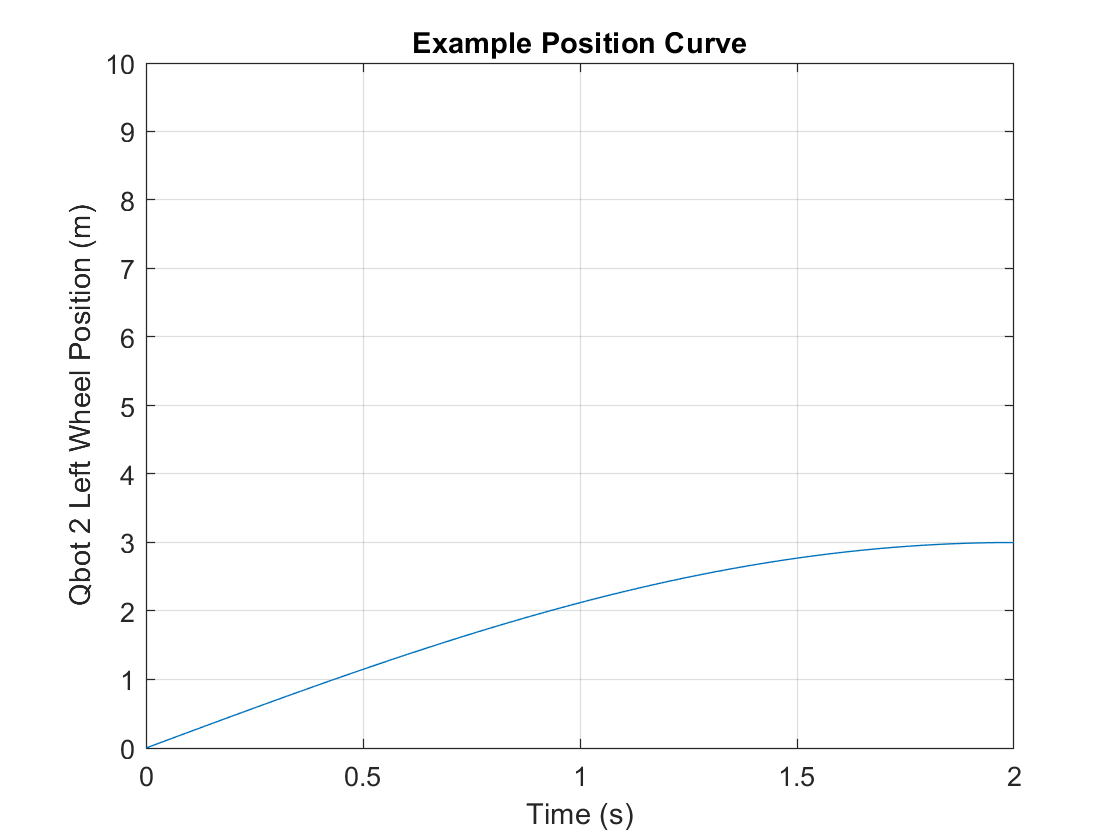

% Position Curve Example

% Select your desired values for r_des and t_travel
r_des =3;  % m
t_travel = 2;  % s

% Build Position Cuve
t = 0 : 1e-3 : t_travel;
r_l = r_des * sin((pi/(2*t_travel)) * t);

% Plot Resulting Curve
figure
plot(t, r_l)
title('Example Position Curve r_l(t)')
xlabel('Time (s)')
xlim([0, t_travel])
ylabel('Qbot 2 Left Wheel Position (m)')
ylim([0 10])
grid on

Now to compute velocity, we simply differentiate or position function.  Doing so leads to the following functions.  


$$v_l \left(t\right)=r_{\mathrm{des}} \frac{\pi \;}{2t_{\mathrm{travel}} }\mathrm{cos}\left(\frac{\pi \;}{2t_{\mathrm{travel}} }t\right),\;\;0<t<t_{\mathrm{travel}}$$


Using the same example values of $r_{\mathrm{des}} =3,\;t_{\mathrm{travel}} =2$, this function becomes:


$$v_{l\;} \left(t\right)=\frac{3\pi \;}{2\cdot 2}\mathrm{cos}\left(\frac{\pi \;}{2\cdot 2}t\right),\;\;0<t<2$$


This implies that the peak velocity during this motion becomes:


$$v_{l,\mathrm{max}} =\frac{3\pi \;}{4}=2\ldotp 3562\frac{m}{s}$$


We know that the Qbot 2 is not capable of moving this speed.  In fact, the max speed of the Qbot 2 is 0.7 m/s.  The reconsile this fact, suppose that in our ground truth simulation that we do not care how long it takes the robot to move from one location to another.  Therefore by always selecting our peak velocity to be our max velocity, we can always meet our Qbot 2 spped kinematic speed constraint.  

Note:  In practice, pushing the robot constantly to its max speed can lead to the robot wearing out prematurely.  Instead, let's constraint the maximum speed to become 0.4 m/s.  


$$\begin{array}{l}
v_{l,\mathrm{max}} =0\ldotp 4\;\frac{m}{s\;}=r_{\mathrm{des}\;} \frac{\pi \;}{2t_{\mathrm{travel}} }\\
t_{\mathrm{travel}} =r_{\mathrm{des}} \frac{\pi \;}{2v_{l,\mathrm{max}} }
\end{array}$$


Now when building our our position curves, we generate a curve that is possible for the Qbot 2 to actually acheive.  

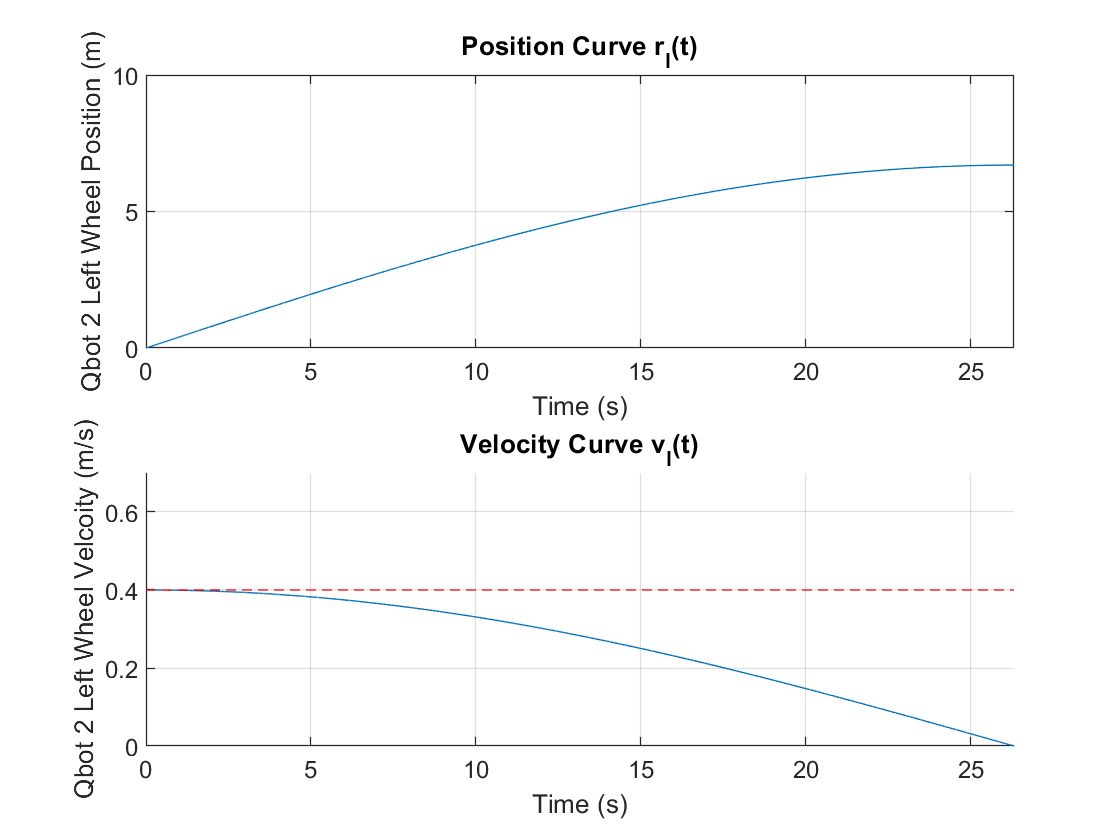

% Position and Velocity Example Curves

% Set Velocity Limit
v_max = 0.4; % m/s

% Select your desired value for r_des 
r_des =6.7;  % m

% Build Position Cuve
t_travel = (r_des * pi) / (2 * v_max);
t = 0 : 1e-3 : t_travel;
r_l = r_des * sin((pi/(2*t_travel)) * t);
v_l = ((r_des*pi)/(2*t_travel)) * cos((pi/(2*t_travel)) * t);

% Plot Resulting Curve
figure
subplot(2, 1, 1)
plot(t, r_l)
title('Position Curve r_l(t)')
xlabel('Time (s)')
xlim([0, t_travel])
ylabel('Qbot 2 Left Wheel Position (m)')
ylim([0 10])
grid on
subplot(2, 1, 2)
hold on
plot(t, v_l)
line([0 t_travel], [v_max v_max], 'Color', 'red', 'LineStyle', '--')
title('Velocity Curve v_l(t)')
xlabel('Time (s)')
xlim([0, t_travel])
ylabel('Qbot 2 Left Wheel Velcoity (m/s)')
ylim([0 0.7])
grid on
hold off